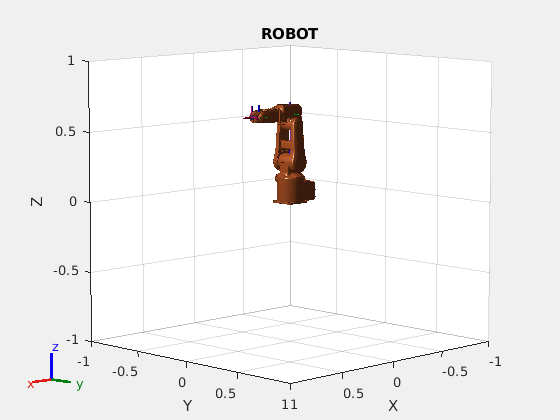

robo = loadrobot('abbIrb120');
ax = show(robo);
title(ax,'ROBOT');
hold('on');

pts = readtable('DataScience/project/archive/newDataset.csv');
pts

pts = 15000×9 table
       q1           q2           q3            q4             q5        q6       x          y         z  
    _________    _________    _________    ___________    __________    __    _______    _______    _____

      0.53124     -0.30922      0.46022    -0.00080491       0.13002    0      0.2553       0.15    0.551
     -0.20053      0.48051     -0.14141     -0.0010425     -0.057845    0       0.492       -0.1    0.475
      0.69637    -0.060094      0.49841     0.00096908       0.12949    0      0.2667      0.223    0.456
    -0.064687      0.43557     -0.45136     -0.0018304      -0.12987    0       0.485    -0.0314     0.62
     -0.66174    -0.012239      0.314


x = pts(:,7);
y = pts(:,8);
z = pts(:,9);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

%plot3(ax,x_d,y_d,z_d);
%hold('off');
robo.BodyNames

ans = 1×8 cell array
    {'base'}    {'link_1'}    {'link_2'}    {'link_3'}    {'link_4'}    {'link_5'}    {'link_6'}    {'tool0'}


i = 1201;
pos = [x_d(i) y_d(i) z_d(i)];
posvec = trvec2tform(pos);
disp(posvec)

    1.0000         0         0    0.1970
         0    1.0000         0   -0.1040
         0         0    1.0000    0.5560
         0         0         0    1.0000



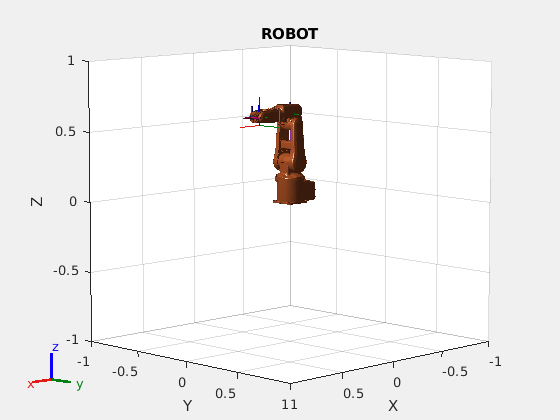

plotTransforms(pos,eul2quat([0 0 0]),FrameSize=0.2);


ik = inverseKinematics("RigidBodyTree",robo);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robo);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);

disp(configSoln);

  1×6 struct array with fields:

    JointName
    JointPosition



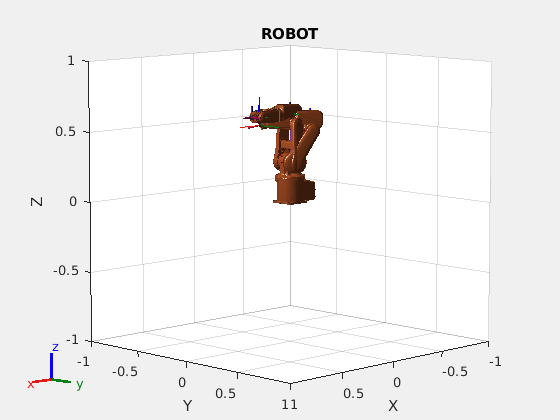

show(robo,configSoln);
hold('off');

pose = getTransform(robo,configSoln,"link_6");
disp(pose);

    0.8623    0.4675    0.1945    0.1970
   -0.4540    0.8839   -0.1119   -0.1040
   -0.2242    0.0082    0.9745    0.5560
         0         0         0    1.0000



**RANDOM JOINT CONFIGURATION FROM GIVEN DATASET** 

config = pts(i,1:6);
config = table2array(config);
disp('COnfig: ')

COnfig: 


disp(config);

   -0.4862   -0.5969    0.6338    0.0082    0.1893         0




home_config = homeConfiguration(robo)

home_config = 1×6 struct array with fields:
    JointName
    JointPosition


for i = 1:6
    home_config(i).JointPosition = config(i);
end
newpose = getTransform(robo,home_config,"link_6");
disp(newpose);

    0.8623    0.4675    0.1945    0.1970
   -0.4540    0.8839   -0.1119   -0.1040
   -0.2242    0.0082    0.9745    0.5560
         0         0         0    1.0000



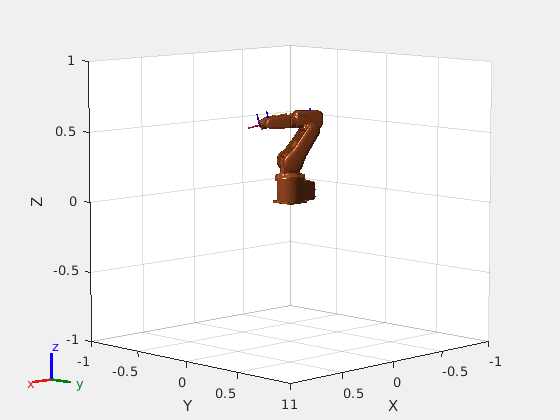

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robo,home_config) 